## Load Impedance Data

clf;
load ImpedanceData.mat; %loads in files freq and z

% Get nice properties out
realZ=real(z);
imagZ=imag(z);
ZabsZ=abs(z);
ZPhaseZ=unwrap(angle(z));

## Extend Range

Default range assumed from 10MHz up

% if 0  % Extends the range if 1, else Ben's code if 0;
%     johnIndex = 1;
% %     freqStart = 1e3;
% %     freqEnd = 5e6;
% %     freqPoints = 2;
% %     pre_freq = linspace(freqStart,freqEnd,freqPoints);
%     pre_freq = 1e6;
% 
%     % freqDiff = freq(2)-freq(1);
%     % zDiff = z(2)-z(1);
%     capacitance = 1/(2*pi.*freq(johnIndex).*abs(z(johnIndex)))   % Z=1/jwC .. C=1/(j2pi*f*|Z|)
%     % zSlope = zDiff/freqDiff;
%     pre_z = (i*2*pi*capacitance*pre_freq).^(-1);
%     pre_freqT = pre_freq.';
%     
%     freq = [pre_freqT; freq];
%     pre_zT = pre_z.';
%     z = [pre_zT; z];
%     
%     realZ=real(z);
%     imagZ=imag(z);
%     Zabs=abs(z);
%     ZPhase=unwrap(angle(z));
% end

## Generate Rational Fit to Impedance

ratFitZ=rationalfit(freq,z);
% sObject=sparameters(z,freq);
% passiveRatFit=makepassive(ratFitZ,sObject);


Prepare frequency response data

fitRespZ = freqresp(ratFitZ,freq);
fitRespMagZ=abs(fitRespZ);
fitRespPhaseZ=angle(fitRespZ);


Passivity arguments if interested

% passiveTest=ispassive(ratFit)
% 
% passiveResp = freqresp(passiveRatFit,freq);
% passiveRespMag = abs(passiveResp);
% passiveRespPhase = angle(passiveResp);


## Plot and compare Magnitude

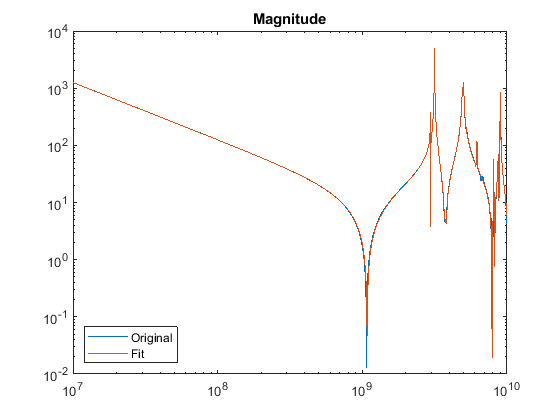

figure()
loglog(freq,Zabs);
hold on
loglog(freq,fitRespMagZ);
% loglog(freq,passiveRespMag);
hold on
title('Magnitude');
legend('Original', 'Fit', 'Location',"southwest")

## Plot/Compare Phase

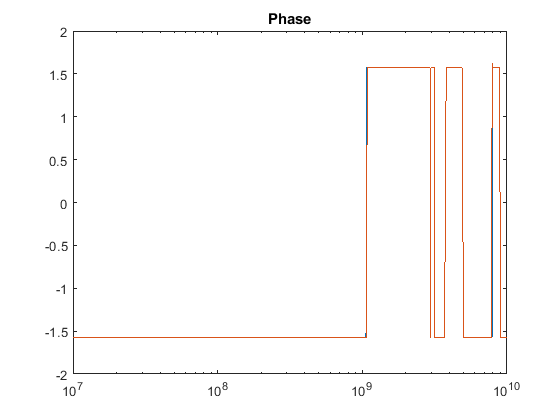

figure()
semilogx(freq,ZPhaseZ);
hold on
semilogx(freq,fitRespPhaseZ);
% semilogx(freq,passiveRespPhase);
title('Phase');

## Plot full fit range

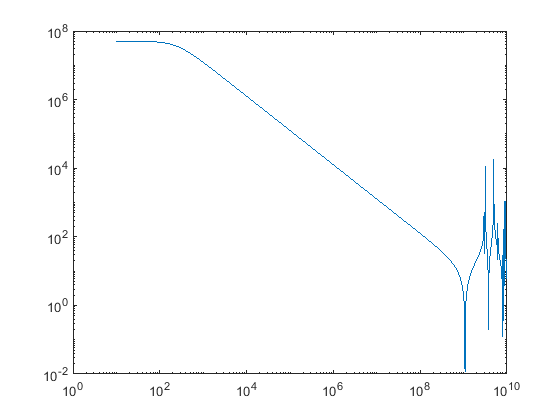

toyMinExp = 1;
toyMaxExp = 10;
toyPts = 10000;
toyFreq = logspace(toyMinExp, toyMaxExp, toyPts);
toyResp = freqresp(ratFitZ,toyFreq);

figure()
loglog(toyFreq, abs(toyResp))

## Convert to S-Param and Generate Circuit

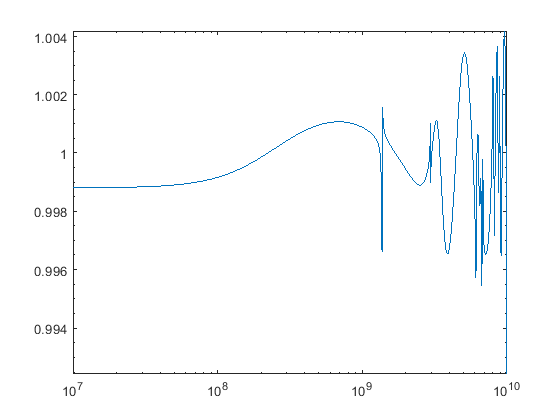

%*** Trying to do manually
% z0=50; %resistance in source
% Vs=data(:,9);
% Pavs=(Vs.^2)/(8*z0);
% Pin=0.5*(V.*conj(I)+conj(V).*I);
% Pr=Pavs-Pin;
% Gamma=sqrt(Pr./Pavs);
% Function to do this for us!!
Gamma=z2gamma(z);
    % sObj=sparameters(Gamma,freq);
    % ratFit=rationalfit(sObj);
% Gamma=makepassive(Gamma);
ratFitG=rationalfit(freq,squeeze(Gamma));%,'TendsToZero',true);
figure()
GammaOut = freqresp(ratFitG, freq);
loglog(freq, abs(GammaOut))

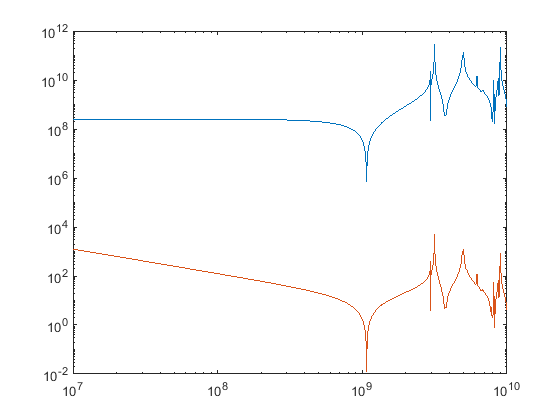

zFromGammaFit = gamma2z(GammaOut,freq);

figure()
loglog(freq, abs(zFromGammaFit))
hold on
loglog(freq, abs(z))
hold off

## Extra Code

% data=frd(z,freq);
% TFsysTest=tfest(data,7);
% 
% zTF=tf(TFsysTest.Numerator,TFsysTest.Denominator);
% %bode(zTF);
% fitTFatFreq=freqresp(zTF,freq);
% fitTFatFreq=squeeze(fitTFatFreq);
% magFitZ=abs(fitTFatFreq);
% phaseFitZ=imag(fitTFatFreq);
% 
% figure()
% title('Magnitude')
% semilogx(freq,Zabs)
% hold on
% yyaxis right
% semilogx(freq,magFitZ);
% 
% figure()
% title('phase')
% semilogx(freq,ZPhase)
% hold on
% yyaxis right
% semilogx(freq,phaseFitZ);